**Генерация функций с сохранением в отдельный файл для оптимизации критерия стабильности **

Кривая равновесия (f_1 = 0)

clear all;

syms a b c l_1 l_2 psi theta_2 theta_2i k_2i
f = h(a,b,c,l_1,psi,theta_2)*cos(theta_2);
matlabFunction(f,'File','equilibriumCurve');


Целевая функция для поиска Paradoxical point

clear all;
syms k_2 theta_2 k_2i theta_2i a b c l_1 psi;

f_1 = equilibriumCurve(a,b,c,l_1,psi,theta_2); % k_2 = f(theta_2)
f_2 = solve(singlePointContactTrajectory(k_2, theta_2, k_2i, theta_2i, l_1), k_2); % k_2 = f(theta_2)
f_2 = f_2(2);

f_1d = diff(f_1, theta_2);
f_2d = diff(f_2, theta_2);

% Условие касания двух кривых: значения кривых совпадают в точке касания и
% производные в точке касания равны
F1 = f_1 - f_2;
F2 = f_1d - f_2d;

% Условие, что точка касания точно принадлежит кривой
F3 = k_2 - f_2;

f = [F1; F2; F3];

matlabFunction(f,'File','objParadoxical');


Определение координат Paradoxical point

clear all;

a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;
% syms a b c l_1 l_2 psi

param = [a, b, c, l_1, psi];
% x0 = [0 0 0 0];
% 
syms k_1 k_2 theta_2 k_2i theta_2i;
vars = [k_2 theta_2 k_2i theta_2i];
% 
% % fun = @(vars)objParadoxical(vars, param);
% 
% % Численное решение системы уравнений: поиск точки касания кривой
% % равновесия и траектории контакта
% options = optimoptions(@fsolve,'Algorithm', 'levenberg-marquardt');
% [out, fval] = fsolve(@(vars)objParadoxical(vars, param),x0, options)

paradoxicalCoord(vars, param)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans =     0.3514    0.3608    0.3346    0.0000


Определение критерия стабильности

clear all;

a = 1; b = 1; c = 1/3;
l_1 = 1; l_2 = 2/3;
psi = pi/2;

% % Диапазоны k_2 и theta_2
% theta_2_max = pi/2;
% theta_2_min = 0;
% k_2_min = 0;
% k_2_max = l_2;
% 
param = [a, b, c, l_1, psi];
syms k_1 k_2 theta_2 k_2i theta_2i;
vars = [k_2 theta_2 k_2i theta_2i];

stabilityCriterion(vars, param)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


ans = 0.6900

Постановка задачи оптимизации геометрии пальца с целью максимизации критерия стабильности

clear all;

l_1 = 1; l_2 = l_1; psi = pi/2;

% camxy = @(X,Y)(4 - 2.1.*X.^2 + X.^4./3).*X.^2 + X.*Y + (-4 + 4.*Y.^2).*Y.^2;
a = 1; b = 1; c = 1/3;
vars = [a b c];
param = [l_1 l_2 psi];

camxy = @(vars)stabilityCriterion(vars, param)

camxy = function_handle with value:
    @(vars)stabilityCriterion(vars,param)



% stabilityCriterion(vars, param)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

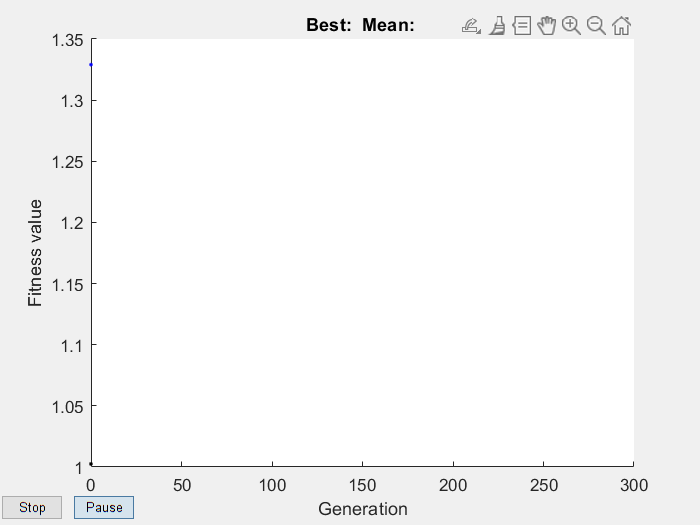


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

numberOfVariables = 3;
lb = [0.5, 0.5, 0.5];
ub = [1, 1, 1];

% Переменные оптимизации
a = optimvar('a','LowerBound',0.1,'UpperBound',2);
b = optimvar('b','LowerBound',0.1,'UpperBound',2);
c = optimvar('c','LowerBound',0.1,'UpperBound',2);
vars = [a b c];
% 
% cam = camxy(vars);

% prob = optimproblem("Objective",@(vars)stabilityCriterion(vars, param), 'ObjectiveSense','max');

rng default % For reproducibility
options = optimoptions('ga','ConstraintTolerance',1e-6,'PlotFcn', @gaplotbestf);

[x,fval] = ga(camxy,numberOfVariables,[],[],[],[],lb,ub, [], options);



% prob.Constraints.cons1 = x*y + x - y + 1.5 <= 0;
% prob.Constraints.cons2 = 10 - x*y <= 0;

% show(prob)

% options = optimoptions(@ga,...
%     'PlotFcn',{@gaplotbestf,@gaplotmaxconstr},...
%     'Display','iter');
% [sol,fval] = solve(prob,"Solver","ga","Options",options)